clear; %Limpa todas as variáveis salvas no workspace
close all; %Fecha todos os gráficos abertos
clc; %Limpa o Command Window

%(J)     moment of inertia of the rotor     0.01 kg.m^2
%(b)     motor viscous friction constant    0.1 N.m.s
%(Ke)    electromotive force constant       0.01 V/rad/sec
%(Kt)    motor torque constant              0.01 N.m/Amp
%(R)     electric resistance                1 Ohm
%(L)     electric inductance                0.5 H

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
D = 0.1;

motor_Pade_Tf = K*(2 - D*s)/(((J*s+b)*(L*s+R)+K^2)*(2 + D*s));
motor_delay_Tf = K*exp(-1*s)/((J*s+b)*(L*s+R)+K^2)


motor_delay_Tf =
 
                         0.01
  exp(-1*s) * ---------------------------
              0.005 s^2 + 0.06 s + 0.1001
 
Continuous-time transfer function.




numg = [-1 20];
deng = [0.5 16 130 200.2];

numroots = roots(numg);
denroots = roots(deng);

motor_Pade_Tf


motor_Pade_Tf =
 
              -0.001 s + 0.02
  ----------------------------------------
  0.0005 s^3 + 0.016 s^2 + 0.13 s + 0.2002
 
Continuous-time transfer function.



  -20.0000
   -9.9975
   -2.0025



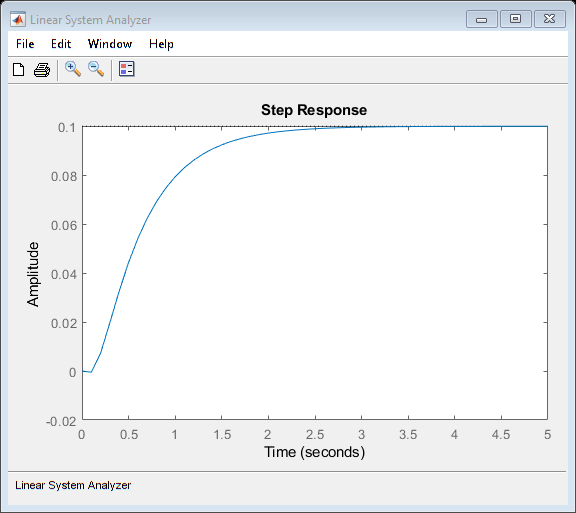

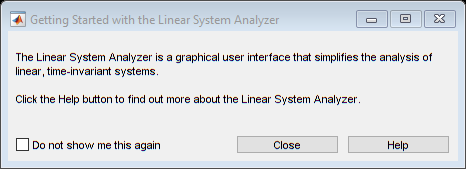

poles = pole(motor_Pade_Tf);
disp(poles)

linearSystemAnalyzer('step', motor_Pade_Tf, 0:0.1:5);
[y,t]= step(motor_delay_Tf); %get the response of the system to a step with amplitude SP
sserror=abs(1-y(end))

sserror = 0.9002

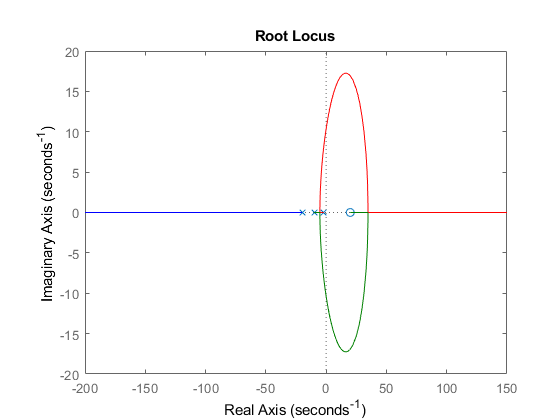


rlocus(motor_Pade_Tf)